xt_scg=x2';
yt_scg=y2';
hiddenLayerSize=50;
scg=fitnet(hiddenLayerSize,'trainscg');
scg.divideFcn = 'divideind';
scg.divideParam.trainInd = tr_lm.trainInd;
scg.divideParam.valInd = tr_lm.valInd;
scg.divideParam.testInd= tr_lm.testInd;
tic
[scg,tr_scg]=train(scg,xt_scg,yt_scg);
T_s=toc

**Performence**

Training set

Y_scg=scg(xt_scg(:,tr_scg.trainInd));
Yt_scg=yt_scg(:,tr_scg.trainInd);
yTrain_scg=(Y_scg'.*(max(y)-min(y))+min(y))';
yTrainTrue_scg=(Yt_scg'.*(max(y)-min(y))+min(y))';
perf_P_scg=rMetrics(yTrainTrue_scg(1,:),yTrain_scg(1,:));
perf_Nu_scg=rMetrics(yTrainTrue_scg(2,:),yTrain_scg(2,:));
row_names_scg=array2table({'Pressure_ratio';'Nusselt ratio'});
T_scg_train=cat(1,perf_P_scg,perf_Nu_scg);
T_scg_train=cat(2,row_names_scg,T_scg_train)

T_scg_train = 2×6 table
           Var1             mae          mse         rmse        Rsq       mape 
    __________________    ________    _________    ________    _______    ______

    {'Pressure_ratio'}    0.048602    0.0045229    0.067253    0.96279    4.2179
    {'Nusselt ratio' }    0.029021    0.0015461    0.039321    0.93255    3.3337


Validation set

Y_val_scg=scg(xt_scg(:,tr_scg.valInd));
Yt_val_scg=yt_scg(:,tr_scg.valInd);
yVal_scg=(Y_val_scg'.*(max(y)-min(y))+min(y))';
yValTrue_scg=(Yt_val_scg'.*(max(y)-min(y))+min(y))';
perf_P_scg=rMetrics(yValTrue_scg(1,:),yVal_scg(1,:));
perf_Nu_scg=rMetrics(yValTrue_scg(2,:),yVal_scg(2,:));
row_names_scg=array2table({'Pressure_ratio';'Nusselt ratio'});
T_scg_val=cat(1,perf_P_scg,perf_Nu_scg);
T_scg_val=cat(2,row_names_scg,T_scg_val)

T_scg_val = 2×6 table
           Var1             mae          mse         rmse        Rsq       mape 
    __________________    ________    _________    ________    _______    ______

    {'Pressure_ratio'}    0.047885    0.0044207    0.066488    0.95654    4.1959
    {'Nusselt ratio' }    0.029426    0.0015653    0.039564    0.93133    3.4076


**Plot**

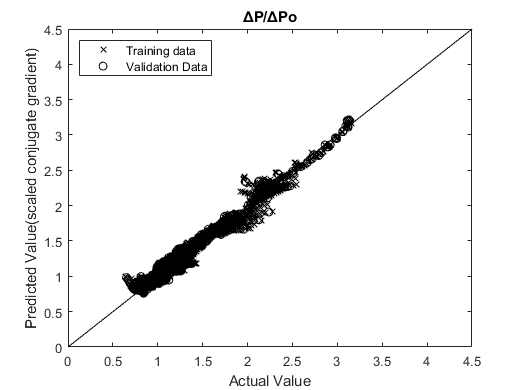

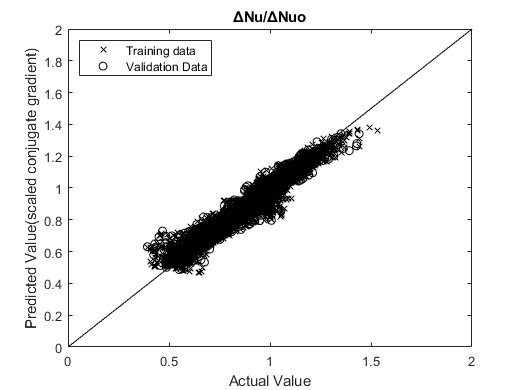

for i=1:2
    figure()
    set(gca,'box','on')
    plot(yTrainTrue_scg(i,:),yTrain_scg(i,:),'x','color','k');hold on;
    plot(yValTrue_scg(i,:),yVal_scg(i,:),'o','color','k');
    plot(0:5,0:5,'color','k');
    if i==1
        xlim([0 4.5])
        ylim([0 4.5])
    else
        xlim([0 2])
        ylim([0 2])
    end
    legend('Training data','Validation Data','','location','northwest')
    ylabel('Predicted Value(scaled conjugate gradient)')
    xlabel('Actual Value')
    if i==1
        title('ΔP/ΔPo');
    else
        title('ΔNu/ΔNuo');
    end
    hold off;
    if i==1
        Plot_SCG_5=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔP÷ΔPo.bmp');
        saveas(gcf,Plot_SCG_5)
    else
        Plot_SCG_5=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔNu÷ΔNuo.bmp');
        saveas(gcf,Plot_SCG_5)
    end
    
end

**Optimization**

%select all and press ctrl+T to enable section
hiddenLayerNo=[1,2,3];
for i=1:50
    tic
    hiddenLayerSize=i;
    %defining the architecture of the Ann
    scg=fitnet(hiddenLayerSize,'trainscg');
    scg.divideFcn = 'divideind';
    scg.divideParam.trainInd = tr_lm.trainInd;
    scg.divideParam.valInd = tr_lm.valInd;
    scg.divideParam.testInd= tr_lm.testInd;

    %training of Ann
    [scg,tr_scg]=train(scg,xt_scg,yt_scg,'useParallel','yes');
    T_scg(i,:)=toc
    
    Y_opt_scg=scg(xt_scg(:,tr_scg.trainInd));
    Yt_opt_scg=yt_scg(:,tr_scg.trainInd);
    Yv_opt_scg=scg(xt_scg(:,tr_scg.valInd));
    Yvt_opt_scg=yt_scg(:,tr_scg.valInd);
    

    yTrain_scg=(Y_opt_scg'.*(max(y)-min(y))+min(y))';
    yTrainTrue_scg=(Yt_opt_scg'.*(max(y)-min(y))+min(y))';
    yVal_scg=(Yv_opt_scg'.*(max(y)-min(y))+min(y))';
    yValTrue_scg=(Yvt_opt_scg'.*(max(y)-min(y))+min(y))';
   
    %rmse
    for j=1:2
        rms_train_scg(i,j)=sqrt(mean((yTrain_scg(j,:)-yTrainTrue_scg(j,:)).^2));
    end   
    for j=1:2
        rms_val_scg(i,j)=sqrt(mean((yVal_scg(j,:)-yValTrue_scg(j,:)).^2));
    end

    %r2
    for j=1:2
        r2_train_scg(i,j)=1 - (sum(((yTrainTrue_scg(j,:) - yTrain_scg(j,:)).^2),2)/sum(((yTrainTrue_scg(j,:) - mean(yTrainTrue_scg(j,:),2)).^2),2));
    end   
    for j=1:2
        r2_val_scg(i,j)=1 - (sum(((yValTrue_scg(j,:) - yVal_scg(j,:)).^2),2)/sum(((yValTrue_scg(j,:) - mean(yValTrue_scg(j,:))).^2),2));
    end
    
    %mape

    for j=1:2
        mape_train_scg(i,j)=mean(abs((yTrainTrue_scg(j,:)-yTrain_scg(j,:))./yTrainTrue_scg(j,:)),2).*100;
    end   
    for j=1:2
        mape_val_scg(i,j)=mean(abs((yValTrue_scg(j,:)-yVal_scg(j,:))./yValTrue_scg(j,:)),2).*100;
    end
    
   name_scg{i} = ['Hidden Layer size: ' num2str(i,'%d')];
   Ta_scg=array2table([rms_train_scg T_scg],"VariableNames",{'RMSE(ΔP/delPo)','RMSE(ΔNu/ΔNuo)','Elapsed Time'});
   Ta_scg.Properties.RowNames=name_scg;
   Tb_scg=array2table([rms_val_scg T_scg],"VariableNames",{'RMSE(ΔP/delPo)','RMSE(ΔNu/ΔNuo)','Elapsed Time'});
   Tb_scg.Properties.RowNames=name_scg;
end

T_scg = 1.9144

T_scg =     1.9144
    1.4493


T_scg =     1.9144
    1.4493
    1.8575


T_scg =     1.9144
    1.4493
    1.8575
    1.8327


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


T_scg =     1.9144
    1.4493
    1.8575
    1.8327
    1.5353
    1.6162
    3.1563
    1.8925
    2.1633
    1.7955


%select all and press ctrl+T to enable section
Ta_scg

Ta_scg = 50×3 table
                             RMSE(ΔP/delPo)    RMSE(ΔNu/ΔNuo)    Elapsed Time
                             ______________    ______________    ____________

    Hidden Layer size: 1         0.32178           0.10896          1.5325   
    Hidden Layer size: 2         0.15552           0.11014          2.2095   
    Hidden Layer size: 3         0.11456           0.10316          1.2487   
    Hidden Layer size: 4         0.15248           0.10874          1.2769   
    Hidden Layer size: 5         0.14728           0.10766          1.4712   
    Hidden Layer size: 6        0.094076          0.073381          4.4052   
    Hidden Layer size: 7         0.10415          0.098805          2.0847   
    Hidden Layer size: 8        0.09893

Tb_scg

Tb_scg = 50×3 table
                             RMSE(ΔP/delPo)    RMSE(ΔNu/ΔNuo)    Elapsed Time
                             ______________    ______________    ____________

    Hidden Layer size: 1         0.32769           0.11075          1.5325   
    Hidden Layer size: 2         0.15656            0.1121          2.2095   
    Hidden Layer size: 3         0.11261           0.10425          1.2487   
    Hidden Layer size: 4         0.15293           0.11038          1.2769   
    Hidden Layer size: 5         0.14953           0.10996          1.4712   
    Hidden Layer size: 6        0.093573          0.073086          4.4052   
    Hidden Layer size: 7         0.10443           0.10016          2.0847   
    Hidden Layer size: 8          0.100

writetable(Ta_scg,'D:/Matlab Drive/Research/Table/Performence_scg(training).xlsx','Sheet',1)
writetable(Tb_scg,'D:/Matlab Drive/Research/Table/Performence_scg(validation).xlsx','Sheet',1)

**Select Optimum no of neuron in hidden layer(rmse)**

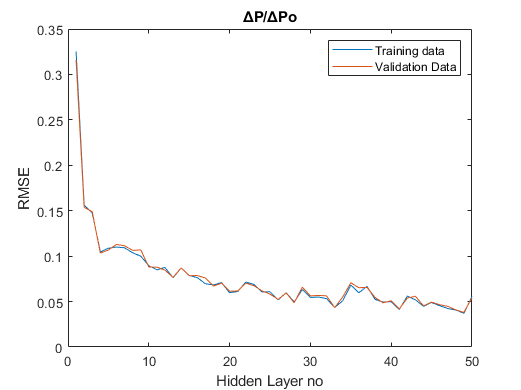

%select all and press ctrl+T to enable section
%pressure
plot(1:i,rms_train_scg(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔP/ΔPo')
plot(1:i,rms_val_scg(:,1));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔP÷ΔPo_optimisation(rmse).bmp');
saveas(gcf,Plot_SCG_6);
hold off;

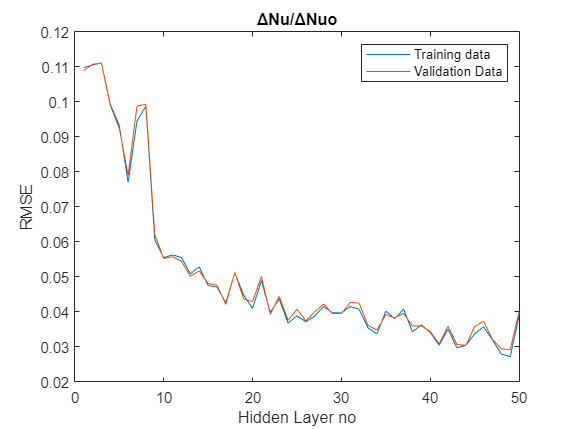


%Nusselt
plot(1:i,rms_train_scg(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('RMSE')
title('ΔNu/ΔNuo')
plot(1:i,rms_val_scg(:,2));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔNu÷ΔNuo_optimisation(rmse).bmp');
saveas(gcf,Plot_SCG_6);
hold off;

**Select Optimum no of neuron in hidden layer(r2)**

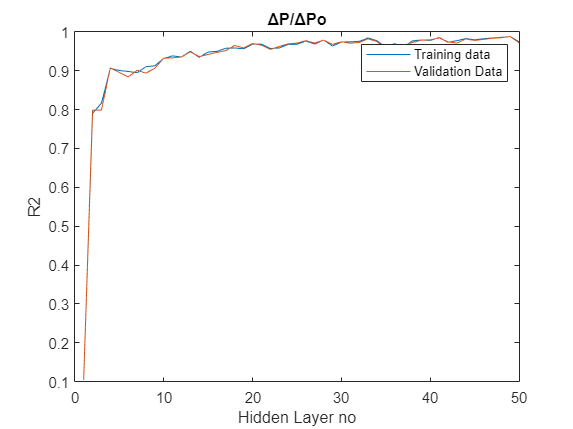

%select all and press ctrl+T to enable section
%pressure
plot(1:i,r2_train_scg(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('R2')
title('ΔP/ΔPo')
plot(1:i,r2_val_scg(:,1));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔP÷ΔPo_optimisation(r2).bmp');
saveas(gcf,Plot_SCG_6);
hold off;

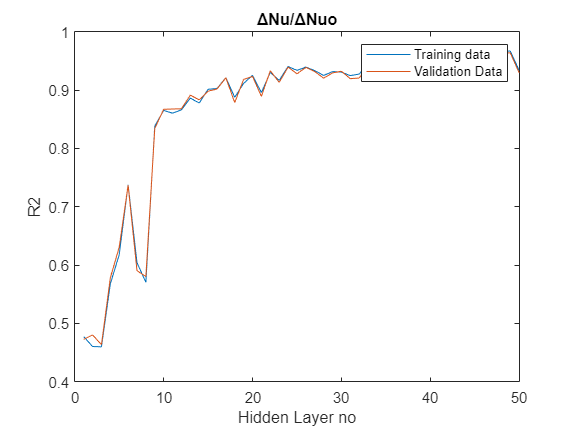


%Nusselt
plot(1:i,r2_train_scg(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('R2')
title('ΔNu/ΔNuo')
plot(1:i,r2_val_scg(:,2));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔNu÷ΔNuo_optimisation(r2).bmp');
saveas(gcf,Plot_SCG_6);
hold off;

**Select Optimum no of neuron in hidden layer(mape)**

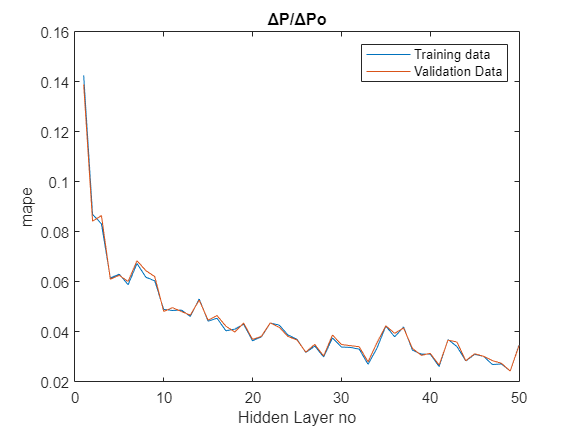

%select all and press ctrl+T to enable section
%pressure
plot(1:i,mape_train_scg(:,1));hold on;
xlabel('Hidden Layer no')
ylabel('mape')
title('ΔP/ΔPo')
plot(1:i,mape_val_scg(:,1));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔP÷ΔPo_optimisation(mape).bmp');
saveas(gcf,Plot_SCG_6);
hold off;

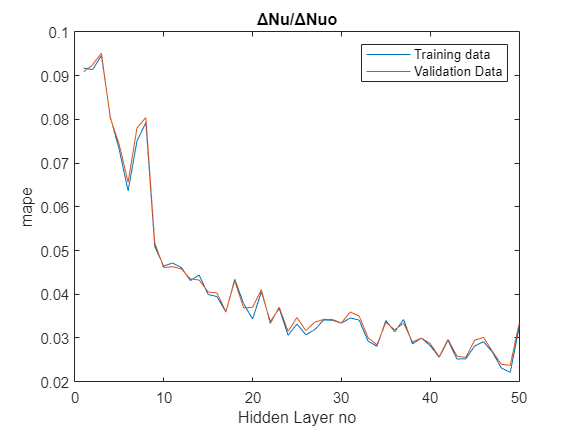


%Nusselt
plot(1:i,mape_train_scg(:,2));hold on;
xlabel('Hidden Layer no')
ylabel('mape')
title('ΔNu/ΔNuo')
plot(1:i,mape_val_scg(:,2));
legend('Training data','Validation Data');
Plot_SCG_6=sprintf('D:/Matlab Drive/Research/Figure/SCG/ΔNu÷ΔNuo_optimisation(mape).bmp');
saveas(gcf,Plot_SCG_6);
hold off;